%Primera Parte: Limpieza y normalizacion de los datos
%Primer Paso: Importar los datos y separarlos

datosCompletos = importdata("accelerometer.csv")

datosCompletos = struct with fields:
          data: [153000×5 double]
      textdata: {'wconfid'  'pctid'  'x'  'y'  'z'}
    colheaders: {'wconfid'  'pctid'  'x'  'y'  'z'}


soloDatos = datosCompletos.data

soloDatos =     1.0000   20.0000    1.0040    0.0900   -0.1250
    1.0000   20.0000    1.0040   -0.0430   -0.1250
    1.0000   20.0000    0.9690    0.0900   -0.1210
    1.0000   20.0000    0.9730   -0.0120   -0.1370
    1.0000   20.0000    1.0000   -0.0160   -0.1210
    1.0000   20.0000    0.9610    0.0820   -0.1210
    1.0000   20.0000    0.9730   -0.0550   -0.1090
    1.0000   20.0000    1.0000    0.0120   -0.1330
    1.0000   20.0000    0.9690   -0.1020   -0.1410
    1.0000   20.0000    0.9730   -0.0590   -0.1250


tiempo = linspace(0,153000,153000)

tiempo = 1.0e+05 *

         0    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0005


datos_x = readvars('accelerometer.csv','Range','C1:C153001')

datos_x =     1.0040
    1.0040
    0.9690
    0.9730
    1.0000
    0.9610
    0.9730
    1.0000
    0.9690
    0.9730


datos_y = readvars('accelerometer.csv','Range','D1:D153001')

datos_y =     0.0900
   -0.0430
    0.0900
   -0.0120
   -0.0160
    0.0820
   -0.0550
    0.0120
   -0.1020
   -0.0590


datos_z = readvars('accelerometer.csv','Range','E1:E153001')

datos_z =    -0.1250
   -0.1250
   -0.1210
   -0.1370
   -0.1210
   -0.1210
   -0.1090
   -0.1330
   -0.1410
   -0.1250


datos_wconfid = readvars('accelerometer.csv','Range','A1:A153001')

datos_wconfid =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


datos_pctid = readvars('accelerometer.csv','Range','B1:B153001')

datos_pctid =     20
    20
    20
    20
    20
    20
    20
    20
    20
    20



%Segundo Paso: Normalizar los datos entre 0 y 1

min_wconfid = min(datos_wconfid)

min_wconfid = 1

max_wconfid = max(datos_wconfid)

max_wconfid = 3


wconfid_norm = (datos_wconfid-min_wconfid)/(max_wconfid-min_wconfid)

wconfid_norm =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0



min_pctid = min(datos_pctid)

min_pctid = 20

max_pctid = max(datos_pctid)

max_pctid = 100


pctid_norm = (datos_pctid-min_pctid)/(max_pctid-min_pctid)

pctid_norm =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0



min_x = min(datos_x)

min_x = -8

max_x = max(datos_x)

max_x = 7.9960


data_x_norm = (datos_x-min_x)/(max_x-min_x)

data_x_norm =     0.5629
    0.5629
    0.5607
    0.5610
    0.5626
    0.5602
    0.5610
    0.5626
    0.5607
    0.5610



min_y = min(datos_y)

min_y = -8

max_y = max(datos_y)

max_y = 7.9960


data_y_norm = (datos_y-min_y)/(max_y-min_y)

data_y_norm =     0.5058
    0.4974
    0.5058
    0.4994
    0.4991
    0.5053
    0.4967
    0.5009
    0.4937
    0.4964



min_z = min(datos_z)

min_z = -5.8670

max_z = max(datos_z)

max_z = 6.0860


data_z_norm = (datos_z-min_z)/(max_z-min_z)

data_z_norm =     0.4804
    0.4804
    0.4807
    0.4794
    0.4807
    0.4807
    0.4817
    0.4797
    0.4790
    0.4804


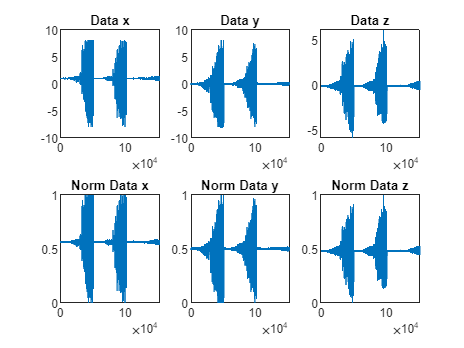


figure()
subplot(2,3,1)
plot(tiempo,datos_x)
title('Data x')

subplot(2,3,4)
plot(tiempo,data_x_norm)
title('Norm Data x')

subplot(2,3,2)
plot(tiempo,datos_y)
title('Data y')

subplot(2,3,5)
plot(tiempo,data_y_norm)
title('Norm Data y')

subplot(2,3,3)
plot(tiempo,datos_z)
title('Data z')

subplot(2,3,6)
plot(tiempo,data_z_norm)
title('Norm Data z')

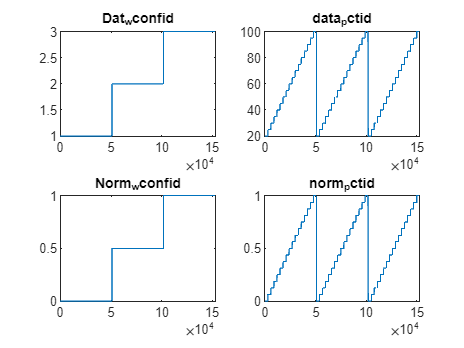


figure()
subplot(2,2,1)
plot(tiempo,datos_wconfid)
title('Dat_wconfid')

subplot(2,2,3)
plot(tiempo,wconfid_norm)
title('Norm_wconfid')

subplot(2,2,2)
plot(tiempo,datos_pctid)
title('data_pctid')

subplot(2,2,4)
plot(tiempo,pctid_norm)
title('norm_pctid')


%Tercer Paso: Obtener datos estadísticos
prom_x=mean(datos_x)

prom_x = 0.9956

prom_y=mean(datos_y)

prom_y = 0.0054

prom_z=mean(datos_z)

prom_z = -0.1178


med_x=median(datos_x)

med_x = 0.9920

med_y=median(datos_y)

med_y = 0.0080

med_z=median(datos_z)

med_z = -0.1250


moda_x=mode(datos_x)

moda_x = 0.9800

moda_y=mode(datos_y)

moda_y = -0.0230

moda_z=mode(datos_z)

moda_z = -0.1210


peaks_x = findpeaks(datos_x)

peaks_x =     1.0000
    1.0000
    1.0120
    1.0120
    1.0040
    1.0390
    1.0080
    0.9920
    1.0310
    1.0310



%señal normalizada
prom_nx=mean(data_x_norm)

prom_nx = 0.5624

prom_ny=mean(data_y_norm)

prom_ny = 0.5005

prom_nz=mean(data_z_norm)

prom_nz = 0.4810


med_nx=median(data_x_norm)

med_nx = 0.5621

med_ny=median(data_y_norm)

med_ny = 0.5006

med_nz=median(data_z_norm)

med_nz = 0.4804


moda_nx=mode(data_x_norm)

moda_nx = 0.5614

moda_ny=mode(data_y_norm)

moda_ny = 0.4987

moda_nz=mode(data_z_norm)

moda_nz = 0.4807


%Cuarto Paso: Cruces a cero y cambios de signo
data_length = length(datos_x)

data_length = 153000

zero_cross_x = zeros(1,153000)

zero_cross_x =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


%{
for i=1:(data_length-1)
    if ((datos_x(i)*datos_x(i+1))<0)
        if(datos_x(i) > 0)
            zero_cross_x(i) = datos_x(i)
        else
            zero_cross_x(i) = datos_x(i+1)
        end
    elseif ((datos_x(i)*datos_x(i+1))==0)
        if (datos_x(i) == 0)
            zero_cross_x(i) = datos_x(i+1)
        else
            zero_cross_x(i) = datos_x(i)
        end
    end
end
figure()
plot(tiempo,zero_cross_x)
title('Cruces por cero en x')
%}
%Segunda Parte: Preprocesamiento de señales continuas
%Primer Paso: FFT
ft_data_x = fft(datos_x)

ft_data_x = 1.0e+05 *

   1.5233 + 0.0000i
  -0.0023 - 0.0023i
  -0.0062 - 0.0054i
   0.0000 + 0.0030i
   0.0019 + 0.0037i
   0.0017 - 0.0106i
  -0.0035 - 0.0011i
  -0.0042 + 0.0058i
   0.0092 - 0.0026i
   0.0005 - 0.0052i


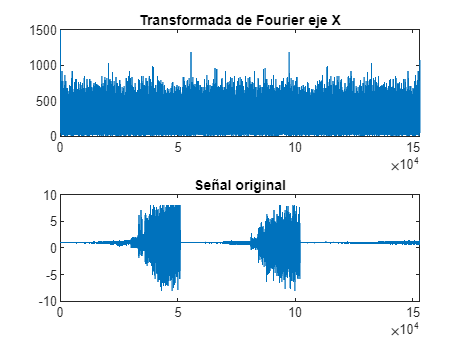

figure()
subplot(2,1,1)
plot(abs(ft_data_x))
ylim([0,1500])
title('Transformada de Fourier eje X')

subplot(2,1,2)
plot(datos_x)
title('Señal original')


ft_data_y = fft(datos_y)

ft_data_y = 1.0e+03 *

   0.8188 + 0.0000i
  -0.1858 + 0.5450i
   0.4308 - 0.3392i
  -0.1553 + 0.2359i
  -0.3146 + 0.5689i
   0.4822 - 0.1291i
   0.0382 - 0.0326i
  -0.3882 - 0.0139i
   0.0619 - 0.0193i
  -0.2080 + 0.0764i


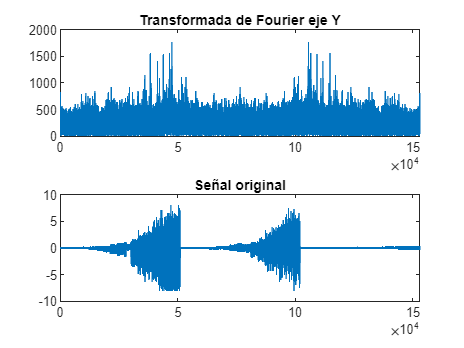

figure()
subplot(2,1,1)
plot(abs(ft_data_y))
ylim([0,2000])
title('Transformada de Fourier eje Y')

subplot(2,1,2)
plot(datos_y)
title('Señal original')


ft_data_z = fft(datos_z)

ft_data_z = 1.0e+04 *

  -1.8019 + 0.0000i
  -0.0321 + 0.0096i
   0.0225 - 0.0159i
  -0.0152 + 0.0550i
   0.0133 + 0.0214i
   0.0229 - 0.0012i
  -0.0177 + 0.0172i
  -0.0060 + 0.0117i
  -0.0027 - 0.0070i
  -0.0085 + 0.0253i


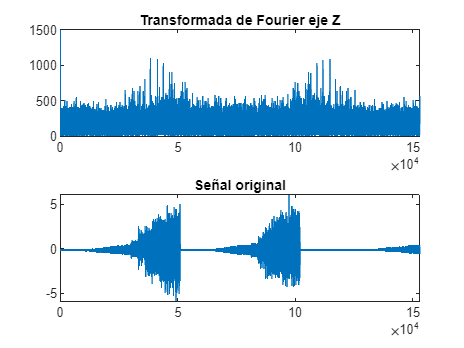

figure()
subplot(2,1,1)
plot(abs(ft_data_z))
ylim([0,1500])
title('Transformada de Fourier eje Z')

subplot(2,1,2)
plot(datos_z)
title('Señal original')


%Segundo paso: transformada Wavelet
%coeficientes de descompo
[cx,lx] = wavedec(datos_x,8,'db2')

cx =    15.9973
   15.9832
   15.9097
   15.9240
   15.9139
   15.9117
   15.8900
   15.9382
   15.9087
   15.9285


lx =          600
         600
        1198
        2393
        4784
        9565
       19127
       38252
       76501
      153000


aprox_x = appcoef(cx,lx,'db2')

aprox_x =    15.9973
   15.9832
   15.9097
   15.9240
   15.9139
   15.9117
   15.8900
   15.9382
   15.9087
   15.9285


[xd1,xd2,xd3,xd4,xd5,xd6,xd7,xd8] = detcoef(cx,lx,[1,2,3,4,5,6,7,8])

xd1 =    -0.0000
   -0.0143
    0.0289
   -0.0138
   -0.0094
    0.0220
   -0.0165
    0.0124
    0.0175
   -0.0426


xd2 =     0.0023
   -0.0097
    0.0157
    0.0045
   -0.0159
    0.0193
   -0.0067
   -0.0063
    0.0120
    0.0105


xd3 =     0.0029
   -0.0225
    0.0296
    0.0248
    0.0032
    0.0011
   -0.0104
   -0.0069
    0.0171
    0.0123


xd4 =     0.0052
   -0.0349
   -0.0055
    0.0026
   -0.0273
   -0.0380
    0.0157
   -0.0258
    0.0001
   -0.0111


xd5 =     0.0086
   -0.0259
    0.0136
    0.0029
   -0.0174
    0.0093
   -0.0026
   -0.0096
   -0.0103
    0.0426


xd6 =     0.0089
   -0.0050
   -0.0029
   -0.0048
   -0.0168
   -0.0057
   -0.0029
    0.0102
    0.0069
    0.0379


xd7 =     0.0056
   -0.0395
    0.0002
    0.0049
   -0.0386
   -0.0033
    0.0064
   -0.0021
    0.0111
   -0.0011


xd8 =     0.0096
   -0.0212
   -0.0155
    0.0074
   -0.0174
   -0.0228
    0.0239
    0.0048
    0.0033
    0.0148


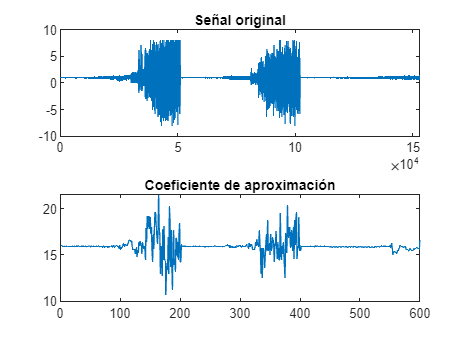


figure()
subplot(2,1,1)
plot(datos_x)
title('Señal original')

subplot(2,1,2)
plot(aprox_x)
title('Coeficiente de aproximación')

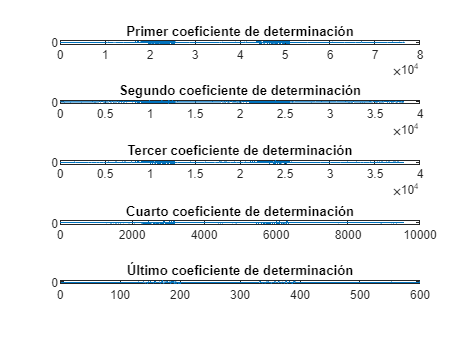


figure()
subplot(5,1,1)
plot(xd1)
title('Primer coeficiente de determinación')

subplot(5,1,2)
plot(xd2)
title('Segundo coeficiente de determinación')

subplot(5,1,3)
plot(xd2)
title('Tercer coeficiente de determinación')

subplot(5,1,4)
plot(xd4)
title('Cuarto coeficiente de determinación')

subplot(5,1,5)
plot(xd8)
title('Último coeficiente de determinación')

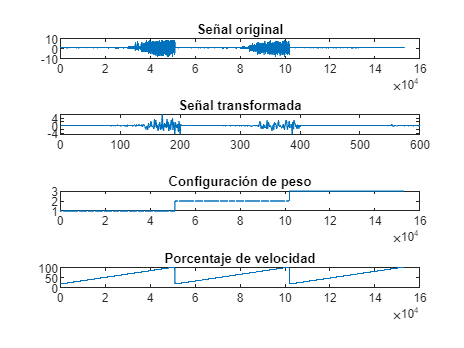


%analisis
figure()
subplot(4,1,1)
plot(datos_x)
title('Señal original')

subplot(4,1,2)
plot(xd8)
title('Señal transformada')

subplot(4,1,3)
plot(datos_wconfid)
title('Configuración de peso')

subplot(4,1,4)
plot(datos_pctid)
title('Porcentaje de velocidad')

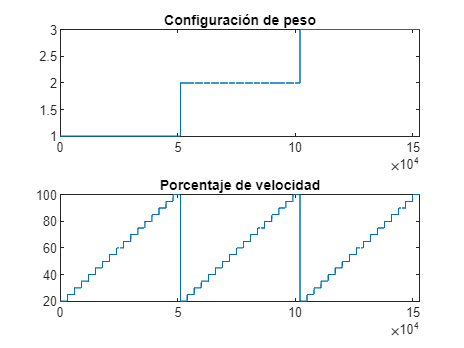


figure()
subplot(2,1,1)
plot(datos_wconfid)
title('Configuración de peso')

subplot(2,1,2)
plot(datos_pctid)
title('Porcentaje de velocidad')